clc;
clear all;

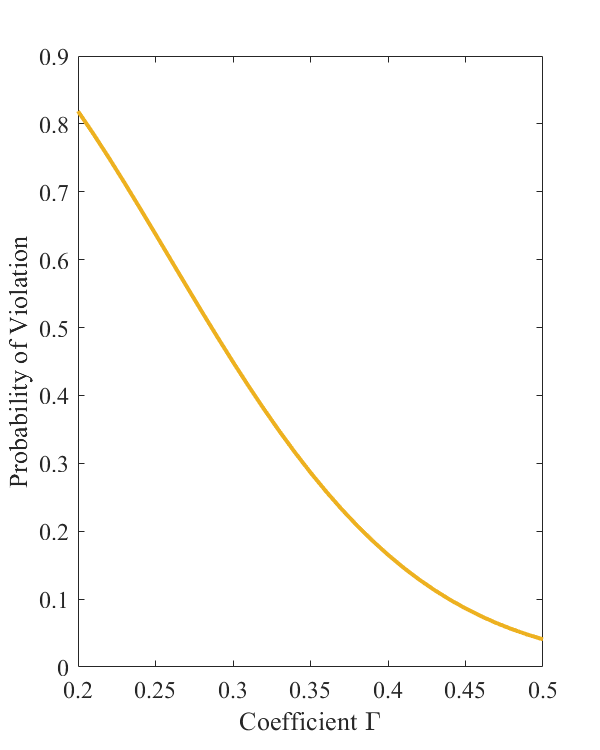

p=0.1;
T=10;
tau_value=0.2:0.01:0.5;
P_true_inverse=zeros(length(tau_value),1);
P_azuma_loose=zeros(length(tau_value),1);
for k=1:length(tau_value)
    tau=tau_value(k);
    P_azuma_loose(k)=exp(-2.*T.*((tau-p).^2));
    for i=0:1:(tau*T)       
        P_true_inverse(k)=P_true_inverse(k)+nchoosek(T,i).*(p.^i).*((1-p).^(T-i));
    end
end
P_true=1-P_true_inverse;
plot(tau_value,P_azuma_loose,'-','color',[0.9290 0.6940 0.1250],'lineWidth',2)

%legend('Data distribution Unknown')
ylabel('Probability of Violation' ,'FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
xlabel('Coefficient \Gamma','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
set(gcf,'Position',[100 100 400 500]);
set(gca,'FontSize',12,'FontName','Times New Roman')

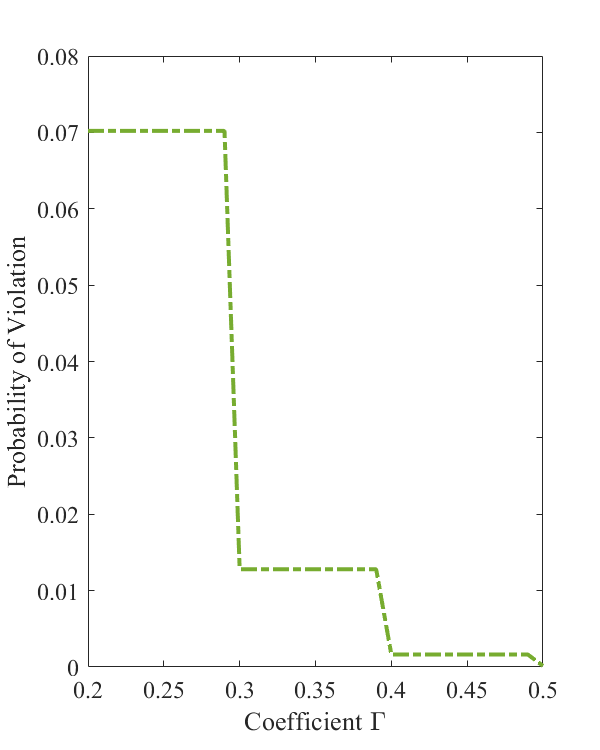

% tau=0.03;
p=0.1;
T=10;
tau_value=0.2:0.01:0.5;
P_true_inverse=zeros(length(tau_value),1);
P_azuma_loose=zeros(length(tau_value),1);
for k=1:length(tau_value)
    tau=tau_value(k);
    P_azuma_loose(k)=exp(-2.*T.*((tau-p).^2));
    for i=0:1:(tau*T)       
        P_true_inverse(k)=P_true_inverse(k)+nchoosek(T,i).*(p.^i).*((1-p).^(T-i));
    end
end
P_true=1-P_true_inverse;
plot(tau_value,P_true,'-.','color',[0.4660 0.6740 0.1880],'lineWidth',2)
%legend('Data Distribution Known', 'Data distribution Unknown')
ylabel('Probability of Violation' ,'FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
xlabel('Coefficient \Gamma','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
set(gcf,'Position',[100 100 400 500]);
set(gca,'FontSize',12,'FontName','Times New Roman')

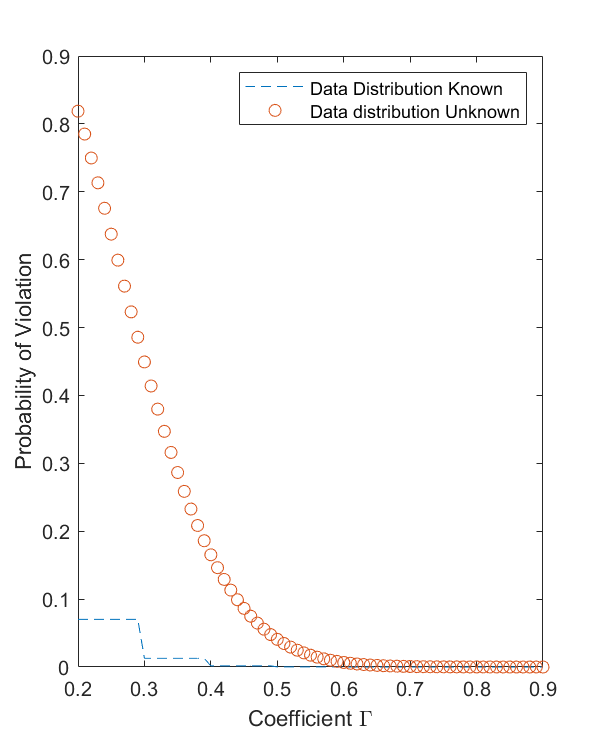

% tau=0.03;
p=0.1;
T=10;
tau_value=0.2:0.01:0.9;
P_true_inverse=zeros(length(tau_value),1);
P_azuma_loose=zeros(length(tau_value),1);
for k=1:length(tau_value)
    tau=tau_value(k);
    P_azuma_loose(k)=exp(-2.*T.*((tau-p).^2));
    for i=0:1:(tau*T)       
        P_true_inverse(k)=P_true_inverse(k)+nchoosek(T,i).*(p.^i).*((1-p).^(T-i));
    end
end
P_true=1-P_true_inverse;
plot(tau_value,P_true,'--',tau_value,P_azuma_loose,'o')
legend('Data Distribution Known', 'Data distribution Unknown')
ylabel('Probability of Violation' )
xlabel('Coefficient \Gamma')

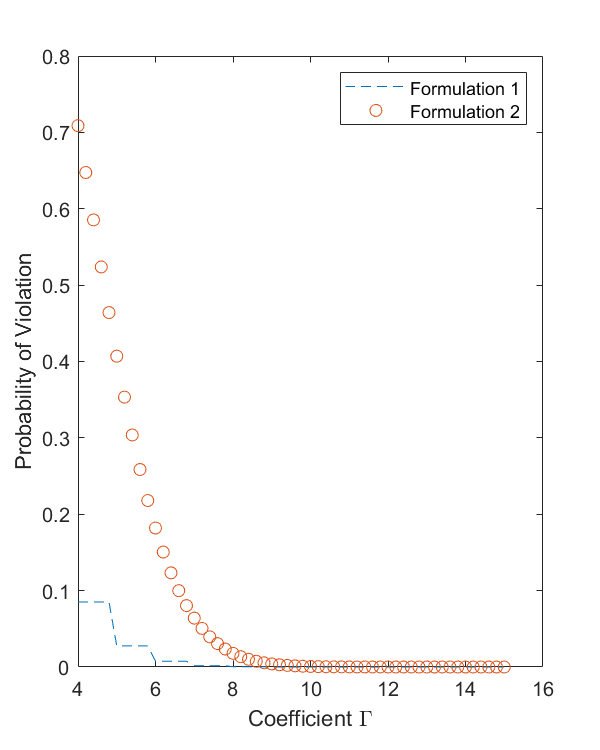

% tau=0.03;
p=0.1;
T=24;
tau_value=4:0.2:15;
P_true_inverse=zeros(length(tau_value),1);
P_azuma_tight=zeros(length(tau_value),1);
for k=1:length(tau_value)
    tau=tau_value(k);
    c=4*(tau-p*T)/T;
    P_azuma_tight(k)=([(1-p).*exp(-c.*p)+p.*exp(c.*(1-p))]^T)*exp(-c*(tau-p*T));
    for i=0:1:tau
        P_true_inverse(k)=P_true_inverse(k)+nchoosek(T,i).*(p.^i).*((1-p).^(T-i));
    end
end
P_true=1-P_true_inverse;
plot(tau_value,P_true,'--',tau_value,P_azuma_tight,'o')
legend('Formulation 1', 'Formulation 2')
ylabel('Probability of Violation' )
xlabel('Coefficient \Gamma')

p_value=0.1:0.1:0.9;
T=10;
tau_value=2:1:9;
P_true_inverse_try=zeros(length(tau_value),length(p_value));
for k=1:length(tau_value)
    tau=tau_value(k);
    for m=1:length(p_value)
        p=p_value(m);
        for i=0:1:tau
            P_true_inverse_try(k,m)=P_true_inverse_try(k,m)+nchoosek(T,i).*(p.^i).*((1-p).^(T-i));
        end
    end
end
P_true_try=1-P_true_inverse_try;
P_true_try

P_true_try =     0.0702    0.3222    0.6172    0.8327    0.9453    0.9877    0.9984    0.9999    1.0000
    0.0128    0.1209    0.3504    0.6177    0.8281    0.9452    0.9894    0.9991    1.0000
    0.0016    0.0328    0.1503    0.3669    0.6230    0.8338    0.9527    0.9936    0.9999
    0.0001    0.0064    0.0473    0.1662    0.3770    0.6331    0.8497    0.9672    0.9984
    0.0000    0.0009    0.0106    0.0548    0.1719    0.3823    0.6496    0.8791    0.9872
    0.0000    0.0001    0.0016    0.0123    0.0547    0.1673    0.3828    0.6778    0.9298
    0.0000    0.0000    0.0001    0.0017    0.0107    0.0464    0.1493    0.3758    0.7361
    0.0000    0.0000    0.0000    0.0001    0.0010    0.0060    0.0282    0.1074    0.3487


clc;
clear all;
p=0.1;
T=24;
tau_value=4:0.2:15;
[P_form_1,P_form_2]=gen_Azuma(p,tau_value,T);
plot(tau_value,P_form_1,'--',tau_value,P_form_2,'o')
legend('Formulation 1', 'Formulation 2')
ylabel('Probability of Violation' )
xlabel('Coefficient \Gamma')